input(1,:)=[6.072747499083493E-9,0.5127045898796013,2.021229880364061E-8,0.5];

m=input(1,1);
psi=input(1,2);
zeta=input(1,3);
H=input(1,4);
Total_experiment_number=10000

Total_experiment_number = 10000

Tmax=100

Tmax = 100

kB=1.3806505e-23;
T=293;%confirmed
delta=0.1;
explosion_limit=1;
explosion_judgement=false;

## Main loop

initialization

imax=Tmax/delta;
v=zeros(imax+1,1);
x=zeros(imax+1,1);
a=zeros(imax+1,1);

sumx=zeros(imax+1,1);
sumx2=zeros(imax+1,1);

loop

for n=1:Total_experiment_number
    v(1,1)=normrnd(0,(kB*T/m)^0.5);%should be random;
    x(1,1)=0;%normrnd(0,(kB*T/(m*psi))^0.5);%no need to be random
    a(1,1)=0;%no need to be random
    BH=(delta^H)*wfbm(H,imax+1);
    for i=1:imax
        KH=i:-1:1;
        x(i+1,1)=x(i,1)+v(i,1)*delta;
        v(i+1,1)=v(i,1)+a(i,1)*delta;
        a(i+1,1)=-(zeta/m)*v(i,1)*delta+(2*zeta*kB*T)^0.5*(BH(i+1)-BH(i))/(m*delta);%ODE
        if 10*i/imax==floor(10*i/imax)
            if max(x(i-imax/10+1:i,1))>=explosion_limit
                explosion_judgement=true;
                disp('explosion!')
                break
            end
        end
    end

calculating sum of x and MSD of x

    sumx=sumx+x;
    for i=1:imax+1
        sumx2(i,1)=sumx2(i,1)+x(i,1)^2;
    end
    

monitoring the progress rate

    if explosion_judgement==true
        break
    end
    if max(x(:,1))>=explosion_limit
        explosion_judgement=true;
        disp('explosion!!!!!!')
        break
    end
    progress_rate=n/Total_experiment_number*100;
    if progress_rate/10==floor(progress_rate/10)
        disp(['progress rate  ',num2str(progress_rate),' %'])
    end
end

progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


## Generating

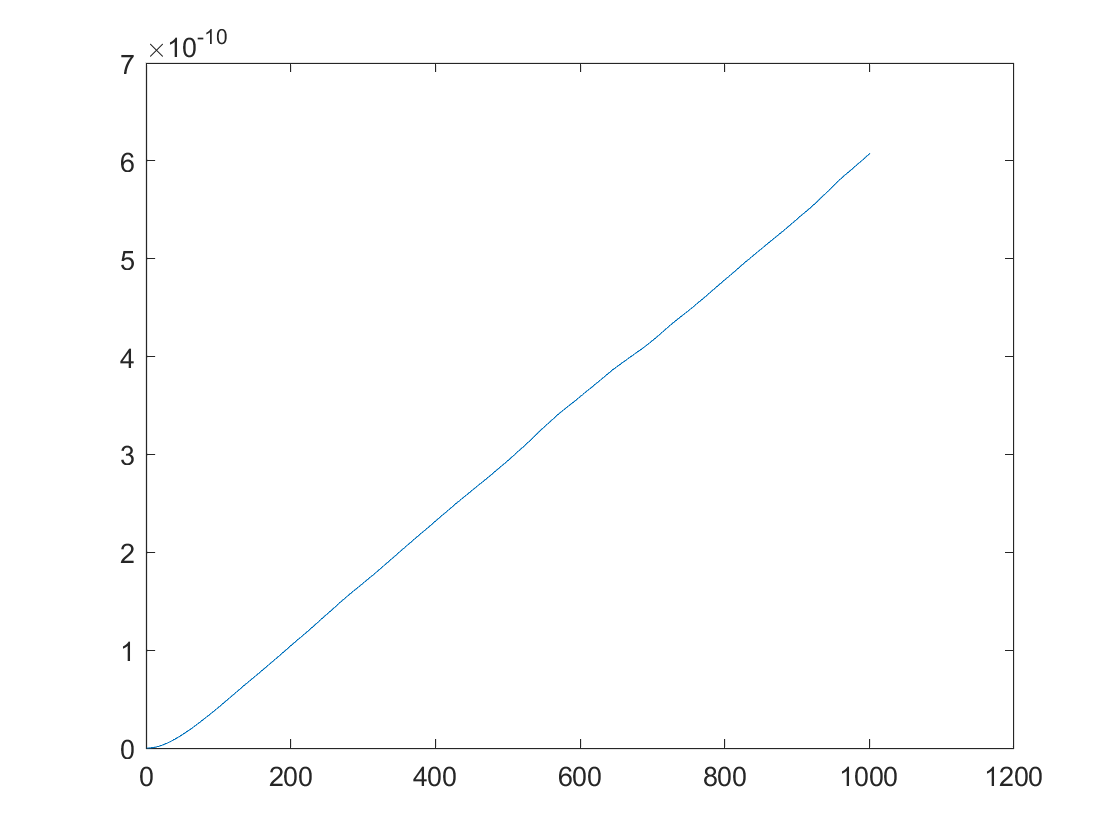

if explosion_judgement==true
    MSD=true;
else
    MSD=zeros(imax+1,1);
    for i=1:imax+1
        MSD(i,1)=sumx2(i,1)/Total_experiment_number-(sumx(i,1)/Total_experiment_number)^2;
    end
end
plot(MSD)

t_scale=delta*(300:1000);
linear_MSD=MSD(300:1000);